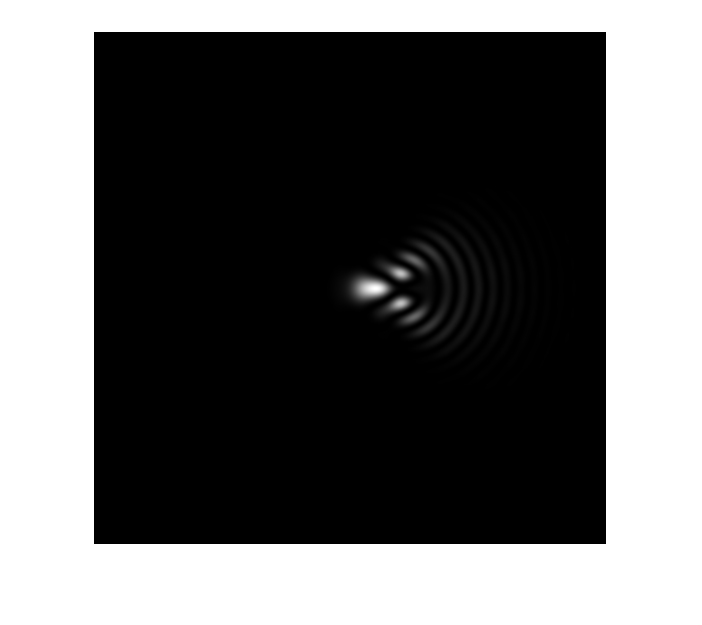

clc;
clear;
close all;
%   Aberration items:
%       C1  Defocus
%       A1  2-Fold astigmatism
%       B2  Axial coma
%       A2  3-Fold astigmatism
%       C3  3rd order spherical aberration
%       S3  Axial star aberration
%       A3  4-Fold astigmatism
%       B4  4th order axial coma
%       D4  3-Lobe aberration
%       A4  5-Fold astigmatism
%       C5  5th order spherical aberration
%       S5  5th order axial star
%       R5  5th order rosette
%       A5  6-Fold astigmatism     
aberration = InitObjectiveLensAberrations_X();
aberration.B2 = 2.5e4; % angstrom

dx = 0.05; % Angstrome
Nx = 512;
Lx = Nx * dx;

voltage = 200; % kV
wavLen = HighEnergyWavLen_X(voltage); % angstrom
aperture = CircApert_X(Lx, Lx, Nx, Nx, wavLen, 20);

otfPhase = AberrationPhaseShift_X(aberration, wavLen, Lx, Lx, Nx, Nx);
otf = exp(-1i * otfPhase) .* aperture;
probe = GenerateProbe_X(otf, 0, 0, Lx, Lx, Nx, Nx);
probeI = abs(probe.^2);
imshow(probeI, []);